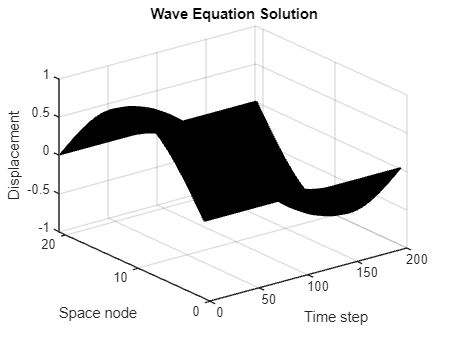

% Wave Equation using Finite Difference Method
clear
clc
L = 1;
T = 1;
c = 1;
N = 20;
M = 200;
h = L/N;
k = T/M;
lambda = c*k/h;
x = 0:h:L;
u = zeros(N+1,M+1);
% Initial displacement
for i=1:N+1
u(i,1) = sin(pi*x(i));
end
% Boundary conditions
u(1,:) = 0;
u(N+1,:) = 0;
% First time step
for i=2:N
u(i,2) = u(i,1) + 0.5*lambda^2*(u(i+1,1)-2*u(i,1)+u(i-1,1));
end
% Finite difference iteration
for j=2:M
for i=2:N
u(i,j+1) = 2*u(i,j) - u(i,j-1) + ...
lambda^2*(u(i+1,j)-2*u(i,j)+u(i-1,j));
end
end
surf(u)
xlabel('Time step')
ylabel('Space node')
zlabel('Displacement')
title('Wave Equation Solution')

    clear
clc

L = 1;
T = 0.5;     % up to t = 0.5
c = 1;

h = 0.1;
k = 0.25;    % matches given table times

N = L/h;     % 10
M = T/k;     % 2

lambda = c*k/h;

x = 0:h:L;
t = 0:k:T;

u = zeros(N+1, M+1);

% -------------------------------
% Initial displacement
% -------------------------------
for i = 1:N+1
    u(i,1) = sin(pi*x(i));
end

% Boundary conditions
u(1,:) = 0;
u(N+1,:) = 0;

% -------------------------------
% First time step (using u_t = 0)
% -------------------------------
for i = 2:N
    u(i,2) = u(i,1) + 0.5*lambda^2 * ...
             (u(i+1,1) - 2*u(i,1) + u(i-1,1));
end

% -------------------------------
% Finite difference iteration
% -------------------------------
for j = 2:M
    for i = 2:N
        u(i,j+1) = 2*u(i,j) - u(i,j-1) + ...
                   lambda^2*(u(i+1,j) - 2*u(i,j) + u(i-1,j));
    end
end

% -------------------------------
% EXACT SOLUTION
% u(x,t) = sin(pi*x)*cos(pi*t)
% -------------------------------
u_exact = zeros(N+1, M+1);

for j = 1:M+1
    for i = 1:N+1
        u_exact(i,j) = sin(pi*x(i)) * cos(pi*t(j));
    end
end

% -------------------------------
% DISPLAY GRID TABLE
% -------------------------------
disp('Grid Table (Numerical)')

Grid Table (Numerical)


disp('-------------------------------------------------------------')

-------------------------------------------------------------


disp(' i    x(i)     u(i,0)     u(i,1)     u(i,2)')

 i    x(i)     u(i,0)     u(i,1)     u(i,2)



for i = 1:N+1
    fprintf('%d   %0.2f    %0.4f    %0.4f    %0.4f\n', ...
        i-1, x(i), u(i,1), u(i,2), u(i,3));
end

0   0.00    0.0000    0.0000    0.0000
1   0.10    0.3090    0.2145    -0.0113
2   0.20    0.5878    0.4080    -0.0214
3   0.30    0.8090    0.5615    -0.0295
4   0.40    0.9511    0.6601    -0.0347
5   0.50    1.0000    0.6941    -0.0364
6   0.60    0.9511    0.6601    -0.0347
7   0.70    0.8090    0.5615    -0.0295
8   0.80    0.5878    0.4080    -0.0214
9   0.90    0.3090    0.2145    -0.0113
10   1.00    0.0000    0.0000    0.0000



% -------------------------------
% COMPARISON TABLE
% -------------------------------
disp(' ')

disp('Comparison Table')

Comparison Table


disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp(' i   x(i)   Num(t1)   Exact(t1)   Num(t2)   Exact(t2)')

 i   x(i)   Num(t1)   Exact(t1)   Num(t2)   Exact(t2)



for i = 1:N+1
    fprintf('%d  %0.2f   %0.4f    %0.4f     %0.4f    %0.4f\n', ...
        i-1, x(i), ...
        u(i,2), u_exact(i,2), ...
        u(i,3), u_exact(i,3));
end

0  0.00   0.0000    0.0000     0.0000    0.0000
1  0.10   0.2145    0.2185     -0.0113    0.0000
2  0.20   0.4080    0.4156     -0.0214    0.0000
3  0.30   0.5615    0.5721     -0.0295    0.0000
4  0.40   0.6601    0.6725     -0.0347    0.0000
5  0.50   0.6941    0.7071     -0.0364    0.0000
6  0.60   0.6601    0.6725     -0.0347    0.0000
7  0.70   0.5615    0.5721     -0.0295    0.0000
8  0.80   0.4080    0.4156     -0.0214    0.0000
9  0.90   0.2145    0.2185     -0.0113    0.0000
10  1.00   0.0000    0.0000     0.0000    0.0000


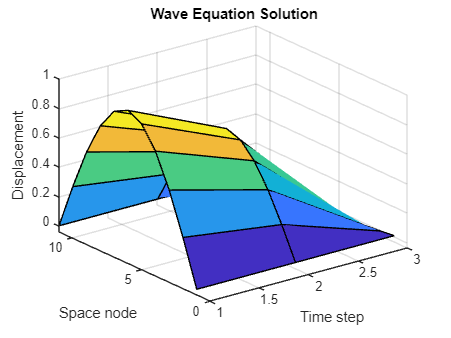


% -------------------------------
% PLOT
% -------------------------------
surf(u)
xlabel('Time step')
ylabel('Space node')
zlabel('Displacement')
title('Wave Equation Solution')

% Wave Equation using Finite Difference Method
clear
clc

L = 1;
T = 0.2;
c = 2;

h = 0.25;
k = 0.1;

N = L/h;
M = T/k;

lambda = c*k/h;

x = 0:h:L;
u = zeros(N+1, M+1);

% -------------------------------
% Initial displacement: u(x,0) = x(1-x)
% -------------------------------
for i = 1:N+1
    u(i,1) = x(i)*(1 - x(i));
end

% -------------------------------
% Boundary conditions
% -------------------------------
u(1,:) = 0;
u(N+1,:) = 0;

% -------------------------------
% First time step (u_t = 0)
% -------------------------------
for i = 2:N
    u(i,2) = u(i,1) + 0.5*lambda^2 * ...
             (u(i+1,1) - 2*u(i,1) + u(i-1,1));
end

% -------------------------------
% Finite difference iteration
% -------------------------------
for j = 2:M
    for i = 2:N
        u(i,j+1) = 2*u(i,j) - u(i,j-1) + ...
                   lambda^2*(u(i+1,j) - 2*u(i,j) + u(i-1,j));
    end
end

% -------------------------------
% GRID TABLE DISPLAY
% -------------------------------
disp('Grid Table (Numerical Solution)')

Grid Table (Numerical Solution)


disp('------------------------------------------------')

------------------------------------------------


disp(' i    x(i)     u(i,0)     u(i,1)     u(i,2)')

 i    x(i)     u(i,0)     u(i,1)     u(i,2)



for i = 1:N+1
    fprintf('%d   %0.2f    %0.4f    %0.4f    %0.4f\n', ...
        i-1, x(i), u(i,1), u(i,2), u(i,3));
end

0   0.00    0.0000    0.0000    0.0000
1   0.25    0.1875    0.1475    0.0531
2   0.50    0.2500    0.2100    0.0900
3   0.75    0.1875    0.1475    0.0531
4   1.00    0.0000    0.0000    0.0000



% -------------------------------
% FULL MATRIX DISPLAY
% -------------------------------
disp(' ')

disp('Full Solution Matrix:')

Full Solution Matrix:


disp(u)

         0         0         0
    0.1875    0.1475    0.0531
    0.2500    0.2100    0.0900
    0.1875    0.1475    0.0531
         0         0         0



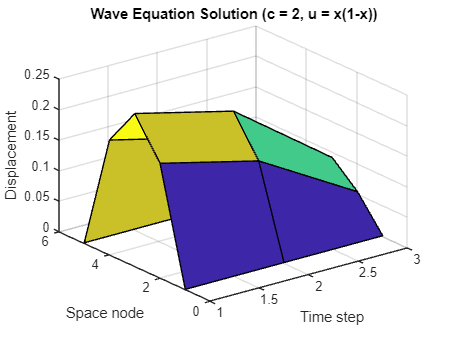


% -------------------------------
% SURFACE PLOT
% -------------------------------
surf(u)
xlabel('Time step')
ylabel('Space node')
zlabel('Displacement')
title('Wave Equation Solution (c = 2, u = x(1-x))')